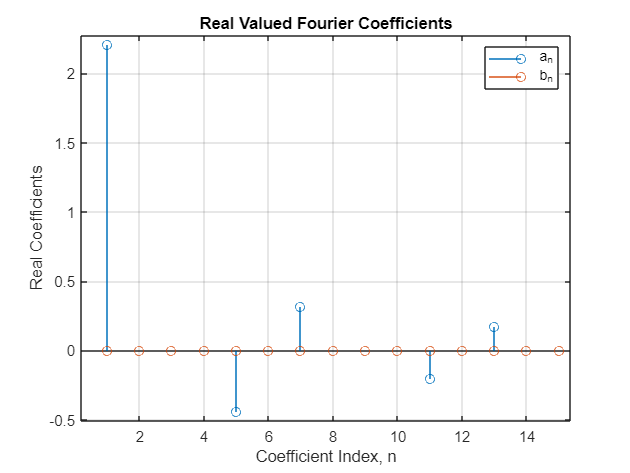

T = 2;
E = 2;

% Define the signal f(t)
f = @(t) E*(mod(t,T) <= (T/6)) - E*((mod(t,T) >= (T/3)) & (mod(t,T) <= (2*T/3))) + E*((mod(t,T) >= (5*T/6)) & (t <= T));

% Define the time vector for one period of the signal
t_period = linspace(0, T, 1000);

% Calculate a1, a2, and a3 using the Fourier series formulas
a1 = round((2/T) * trapz(t_period, f(t_period) .* cos(2*pi*t_period/T)), 2);
a2 = round((2/T) * trapz(t_period, f(t_period) .* cos(4*pi*t_period/T)), 2);
a3 = round((2/T) * trapz(t_period, f(t_period) .* cos(6*pi*t_period/T)), 2);

% Calculate P1, P2, and P3 using the Fourier series formulas
P1 = round((a1^2)/2, 2);
P2 = round((a2^2)/2, 2);
P3 = round((a3^2)/2, 2);

% Calculate PT using the Parseval's theorem
N = 100;
a = zeros(1, N+1);
b = zeros(1, N+1);

for n = 0:N
    cosTerm = cos(2*pi*n*t_period/T);
    sinTerm = sin(2*pi*n*t_period/T);
    a(n+1) = round((2/T) * trapz(t_period, f(t_period) .* cosTerm), 2);
    b(n+1) = round((2/T) * trapz(t_period, f(t_period) .* sinTerm), 2);
end

stem(0:N, a)
hold on
stem(0:N, b)
hold off
xlabel ('Coefficient Index, n' )
ylabel( 'Real Coefficients')
legend('a_n','b_n')
title('Real Valued Fourier Coefficients')
grid on;

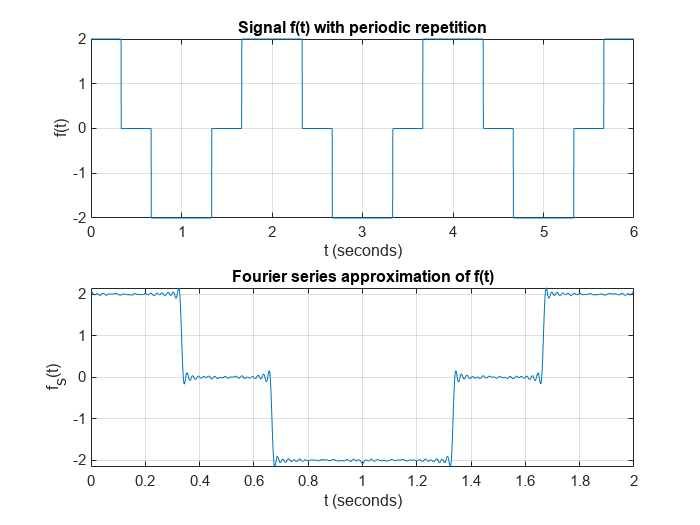


PT = round((1/T) * sum(abs(a).^2 + abs(b).^2), 2);

% Calculate the ratios of P3/PT and P2/PT
ratio_P1 = round((P1/PT)*100, 2);
ratio_P3 = round((P3/PT)*100, 2);
ratio_P2 = round((P3/PT)*100, 2);

% Plot both the original signal and its Fourier series approximation
f_periodic = repmat(f(t_period), 1, 3);
f_s = zeros(size(t_period));

for n = 0:N
    cosTerm = cos(2*pi*n*t_period/T);
    sinTerm = sin(2*pi*n*t_period/T);
    f_s = f_s + a(n+1)*cosTerm + b(n+1)*sinTerm;
end

figure;
subplot(2,1,1);
plot(linspace(0, 3*T, length(f_periodic)), f_periodic);
xlabel('t (seconds)');
ylabel('f(t)');
title('Signal f(t) with periodic repetition');
grid on;

subplot(2,1,2);
plot(t_period, f_s);
xlabel('t (seconds)');
ylabel('f_s(t)');
title('Fourier series approximation of f(t)');
grid on;


% Display the results
disp(['a1 = ', num2str(a1)]);

a1 = 2.21


disp(['a2 = ', num2str(a2)]);

a2 = 0


disp(['a3 = ', num2str(a3)]);

a3 = 0


disp(['P1 = ', num2str(P1)]);

P1 = 2.44


disp(['P2 = ', num2str(P2)]);

P2 = 0


disp(['P3 = ', num2str(P3)]);

P3 = 0


disp(['P1/PT = ', num2str(ratio_P1),'%']);

P1/PT = 91.39%


disp(['P3/PT = ', num2str(ratio_P3),'%']);

P3/PT = 0%


disp(['P2/PT = ', num2str(ratio_P2),'%']);

P2/PT = 0%
